syms s;
G1 = 1/(s^2+2*s+26);
G2 = s/(s+5);


%a) Serie

serie=G1*G2;

[n d]=numden(serie);

Fdt_serie=tf(sym2poly(n),sym2poly(d))


Fdt_serie =
 
             s
  ------------------------
  s^3 + 7 s^2 + 36 s + 130
 
Continuous-time transfer function.



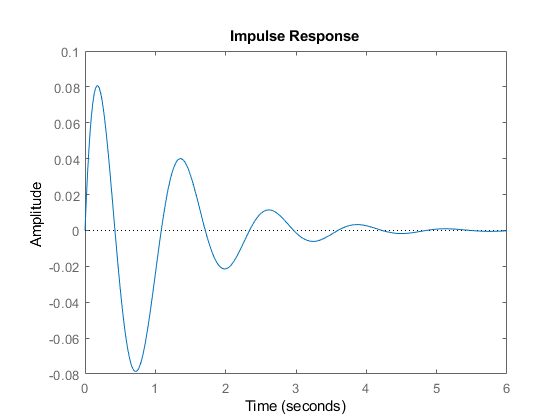


impulse(Fdt_serie);

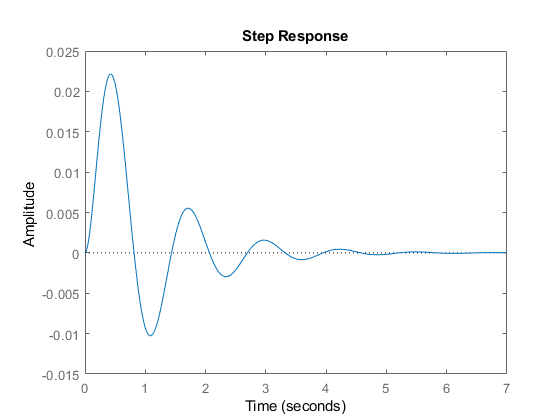

step(Fdt_serie);



%b) Paralelo

paralelo=G1+G2;

[n d]=numden(paralelo);

Fdt_paralelo=tf(sym2poly(n),sym2poly(d))


Fdt_paralelo =
 
   s^3 + 2 s^2 + 27 s + 5
  ------------------------
  s^3 + 7 s^2 + 36 s + 130
 
Continuous-time transfer function.



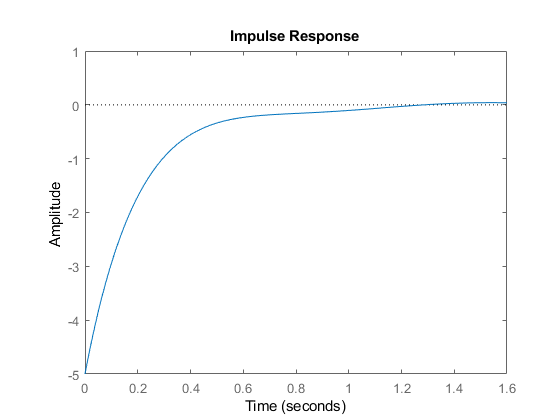


impulse(Fdt_paralelo);

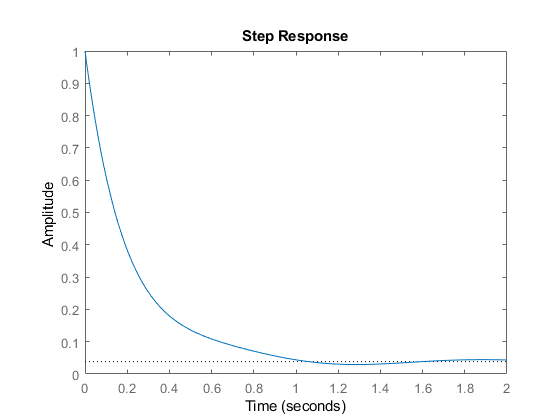

step(Fdt_paralelo);


%c) G2 en realimentación negativa

realimentado_neg=G1/(1+G1*G2);

[n d]=numden(realimentado_neg);

Fdt_realimentado_neg=tf(sym2poly(n),sym2poly(d))


Fdt_realimentado_neg =
 
           s + 5
  ------------------------
  s^3 + 7 s^2 + 37 s + 130
 
Continuous-time transfer function.



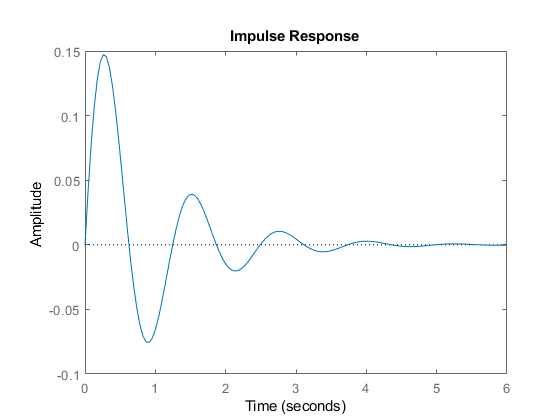


impulse(Fdt_realimentado_neg);

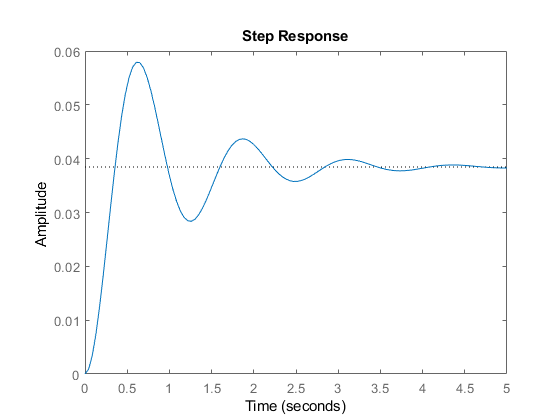

step(Fdt_realimentado_neg);